# **RT-QIBC analysis**

**FarRed2: EdU**

**YFP1: Chromatin-bound Cdc45**

**POI(:,2): APC/C inactivation time**

## **Load Data**

%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
        'PCNA no dox',2,2:3,1:4,[0 0 0],'PCNA','Dox-'; %1
        'PCNA dox',2,4:11,1:4,[0 0 0],'PCNA','Dox+'; %1
        
        'RPA1 no dox',3,2:3,1:4,[0 0 0],'RPA1','Dox-'; %1
        'RPA1 dox',3,4:11,1:4,[0 0 0],'RPA1','Dox+'; %1
        
        'RPA2 no dox',4,2:3,1:4,[0 0 0],'RPA2','Dox-'; %1
        'RPA2 dox',4,4:11,1:4,[0 0 0],'RPA2','Dox+'; %1
        
        'MCM2 no dox',5,2:3,1:4,[0 0 0],'MCM2','Dox-'; %1
        'MCM2 dox',5,4:11,1:4,[0 0 0],'MCM2','Dox+';%1
        
    };


load([dataDir filesep 'C124_data.mat'],'S');
%S = loadData_C124(conditions, dataDir);
framesPerHr = 60/10;
frameDrugAdded = 0;
frameEdU = 0;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;


**Load data into table**

conds=[1:8];
poiAligned=2;
offset=0;

dfTotal = table();

gateVals = {{},{},{},{},{},{},{},{}};
rangeVals = {{[]},{[]},{[]},{[]},{[]},{[]},{[]},{[]}};

for i=1:length(conds)
   % ind = true(size(S(conds(i)).sigNuc(:,1))) ;
    ind = S(conds(i)).dna< 2^19.75;
    time=(numFrames-(S(conds(i)).POI(ind,poiAligned)-offset))/framesPerHr;
    cdt1=(S(conds(i)).sigNuc(ind,end));
    stain=(S(conds(i)).YFP1(ind));
    %stain=(S(conds(i)).FarRed1(ind)-S(conds(i)).FarRed1cyt(ind));
    edu=(S(conds(i)).FarRed1(ind));
    gates = gateVals{i};
    for j=1:length(gates)
        %gateData = S(conds(i)).(gates{j})(ind);
        gateData = S(conds(i)).(gates{j})(ind,end);
        inds = gateData < rangeVals{i}{j}(2) & gateData > rangeVals{i}{j}(1);
        time = time(inds);
        cdt1 = cdt1(inds);
        edu = edu(inds);
        stain = stain(inds);
    end
    
    inds = time >= 1 &  time <= 2;
    time = time(inds);
    cdt1 = cdt1(inds);
    edu = edu(inds);
    stain = stain(inds);
   
    cdt1(cdt1<0.0001) = .0001;
    edu(edu<0.0001) = .0001;
    stain(stain<0.0001) = .0001;
    stainNorm = (stain)./edu;

    treatment = repmat(categorical(conditions(conds(i),6)),numel(time),1);
    doxTreatment = repmat(categorical(conditions(conds(i),7)),numel(time),1);
    phase = repmat(categorical("S"),numel(time),1);
    dfTotal = [dfTotal;table(treatment,phase, doxTreatment,time,cdt1,edu,stain,stainNorm)];
end

% dfTotal = movevars(dfTotal,'drugTreatment','After','doxTreatment');

for i=1:length(conds)
    
    ind = log2(S(conds(i)).dna) < 19.75 & S(conds(i)).apcNuc(:,end) < 10 & S(conds(i)).FarRed1 < 2^6;
    cdt1=(S(conds(i)).sigNuc(ind,end));
    stain=(S(conds(i)).YFP1(ind));
    %stain=(S(conds(i)).FarRed1(ind)-S(conds(i)).FarRed1cyt(ind));
    edu=(S(conds(i)).FarRed1(ind));
    
    cdt1(cdt1<0.0001) = .0001;
    edu(edu<0.0001) = .0001;
    stain(stain<0.0001) = .0001;
    stainNorm = (stain)./edu;
    
    time = repmat(0,numel(cdt1),1);
    treatment = repmat(categorical(conditions(conds(i),6)),numel(cdt1),1);
    doxTreatment = repmat(categorical(conditions(conds(i),7)),numel(time),1);
    phase = repmat(categorical("G1"),numel(time),1);

    dfTotal = [dfTotal; table(treatment,phase, doxTreatment,time,cdt1,edu,stain,stainNorm)];
end


%dfTotal = dfTotal(dfTotal.cdc45 < 10000,:);

Subset based on cdt1 expression

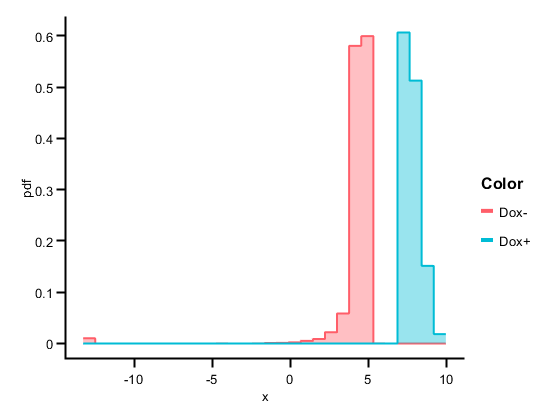

ordering given as values


dfGated = dfTotal((log2(dfTotal.cdt1) > 7 & log2(dfTotal.cdt1) < 10 & dfTotal.doxTreatment == 'Dox+') |...
    dfTotal.doxTreatment == 'Dox-',:);

g= gramm('x',log2(dfGated.cdt1),'color',dfGated.doxTreatment);
g.set_order_options('color',{'Dox-','Dox+'});
g.stat_bin('geom','stairs','fill','transparent','normalization','pdf');
figure,
g.draw();

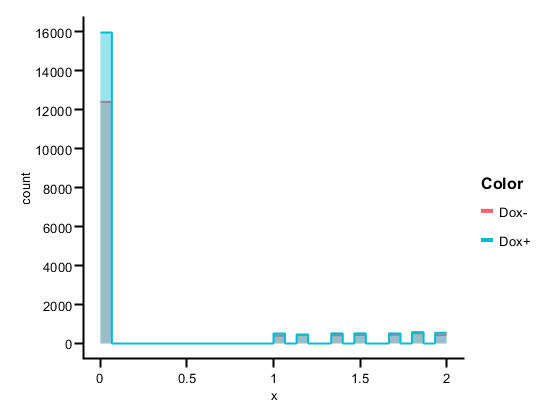

ordering given as values


cells = 824

cells = 940

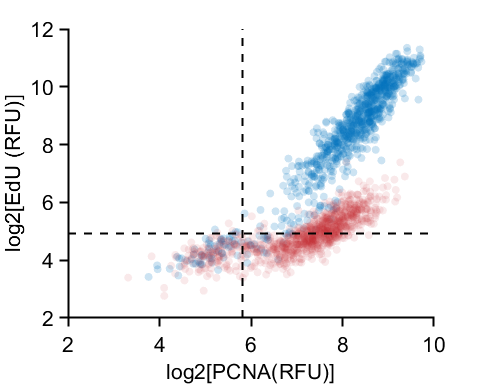


g= gramm('x',dfGated.time(dfGated.treatment ~= 'G1'),'color',dfGated.doxTreatment(dfGated.treatment ~= 'G1'));
g.set_order_options('color',{'Dox-','Dox+'});
g.stat_bin('geom','stairs','fill','transparent');
figure,
g.draw();

**comparing ND-Cdt1 expression on MCM loading**

conds={'Dox-','Dox+','Dox-','Dox+'};
phase = {'G1','G1','S','S'};
names = {'G1 DOX-','G1 DOX+','S DOX-','S DOX+'};
colors = [0 113 188; 193 39 45]/255;
colorval = [1 2 1 2];
ally = [];
group = [];
index = 0;

stain = 'MCM2';
for i=1:length(conds)
    data = dfGated(dfGated.treatment == stain,:);
    data = data(data.doxTreatment == conds{i} & data.phase == phase{i},:);

    xdata = log2(data.stain);

    index = index + 1;
    ally = [ally; xdata];
    group = [group; (index)*ones(size(xdata))];
    n(i) = sum(inds);

end
    n

n =         3418        3418        3418        3418


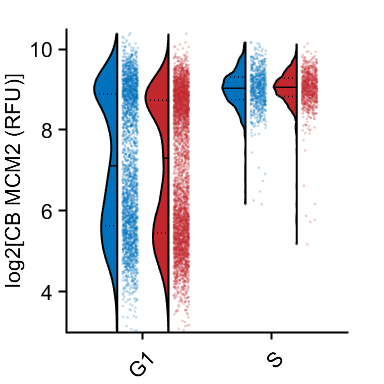

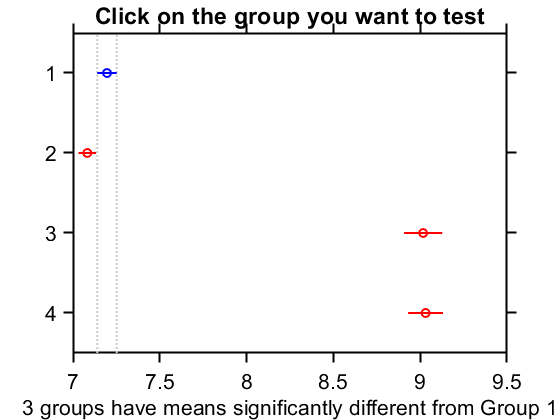



cols = repmat({colors(1,:),colors(2,:),colors(1,:),colors(2,:)}',1,1);
groupcol = repmat([colors([1 2 1 2],:)],1,1);
groups = 1:max(group);
offsetx = floor((groups - 1)/2) * .5;
xkey = groups + offsetx;

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],'xValues',xkey);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols) 

hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.25);
ylabel([ 'log2[CB MCM2 (RFU)]'])
% xticks([2 5 8 11 14])
xticks(xkey(1:2:length(xkey)-1)+.5)
% xticklabels(names)
xticklabels({'G1','S'})
ylim([3 10.5])
xtickangle(45)


% pbaspect([1 1 1])
print_pdf([pwd() '\Figs\MCM2.pdf'])

**comparing ND-Cdt1 expression on EdU**

conds={'Dox-','Dox+','Dox-','Dox+'};
phase = {'G1','G1','S','S'};
names = {'G1 DOX-','G1 DOX+','S DOX-','S DOX+'};
colors = [0 113 188; 193 39 45]/255;
colorval = [1 2 1 2];
ally = [];
group = [];
index = 0;

stain = 'MCM2';
% stand = median(dfGated.stain(dfGated.treatment == stain & dfGated.doxTreatment == 'Dox-' & dfGated.drugTreatment  == 'DMSO' & dfGated.phase == 'S' ));
for i=1:length(conds)
    data = dfGated(dfGated.treatment == stain,:);
    data = data(data.doxTreatment == conds{i} & data.phase == phase{i},:);
    xdata = log2(data.edu);

    if length(xdata) > 1000
        xdata = randsample(xdata,1000,false);
    end


    index = index + 1;
    ally = [ally; xdata];
    group = [group; (index)*ones(size(xdata))];
    n(i) = sum(inds);

end
    n

n =         3418        3418        3418        3418


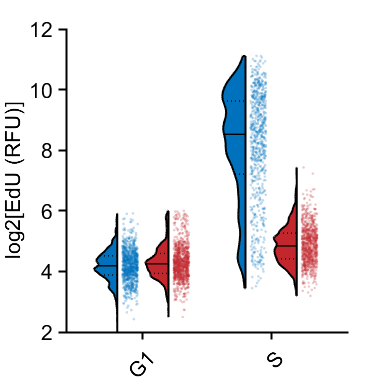


cols = repmat({colors(1,:),colors(2,:),colors(1,:),colors(2,:)}',1,1);
groupcol = repmat([colors([1 2 1 2],:)],1,1);
groups = 1:max(group);
offsetx = floor((groups - 1)/2) * .5;
xkey = groups + offsetx;

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],'xValues',xkey);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
set(h{1},{'FaceColor'},cols) 

hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.25);
ylabel([ 'log2[EdU (RFU)]'])
% xticks([2 5 8 11 14])
xticks(xkey(1:2:length(xkey)-1)+.5)
% xticklabels(names)
xticklabels({'G1','S'})
ylim([2 12])
xtickangle(45)


% pbaspect([1 1 1])
print_pdf([pwd() '\Figs\EdU.pdf'])